clear
close all
clc

## Dati

load("data_stud.mat")
M=otto; %matrice dati sperimentali
h=167; %altezza individuo [cm]
m=61; %peso individuo[Kg]
f=1/20; %frequenza di campionamento [Hz]
time=0:f:(size(M,1)-1)*f;
M1_M2=24; %distanza tra i marker M1 ed M2 [mm]
g=9.81; %accelerazione di gravità terrestre [m/s^2]

## STEP2.1 Schema cinematico

Conoscendo le posizioni dei marker è possibile realizzare un'animazione che visualizzi il movimento dei punti e, quindi, delle aste che modellizzano la situazione reale.

Warning: se questa porzione di codice (relativa allo step2.1) viene eseguita prima della porzione seguente (relativa allo step3.1) risulterà un errore, poichè le posizione del marker M2 vengono definite allo step successivo.

%N.B.: deve essere eseguito prima lo STEP3.1 
%{
hfig=figure;
writeObj=VideoWriter('schema.avi');
writeObj.FrameRate=20;
open(writeObj)
for ii=1:length(time)
    try
        delete(h1)
        delete(h2)
        delete(h3)
        delete(h4)
        delete(pallino)
    end
    h1=line([M(ii,1)/10 M(ii,3)/10],[M(ii,2)/10 M(ii,4)/10]);
    set(h1,'color','r','linewidth',2)
    h2=line([M2(ii,1)/10 M(ii,5)/10],[M2(ii,2)/10 otto(ii,6)/10]);
    set(h2,'color','g','linewidth',2)
    h3=line([M(ii,5)/10 M(ii,7)/10],[M(ii,6)/10 otto(ii,8)/10]);
    set(h3,'color','b','linewidth',2)
    h4=line([M(ii,3)/10 M(ii,5)/10],[M(ii,4)/10 otto(ii,6)/10]);
    set(h4,'color','y','linewidth',2)
    hold on
    pallino=plot([M(ii,1)/10 M(ii,3)/10 M(ii,5)/10 M(ii,7)/10 M2(ii,1)/10],[M(ii,2)/10 ...
        M(ii,4)/10 M(ii,6)/10 M(ii,8)/10 M2(ii,2)/10],'ok');
    axis equal
    axis([-35 30 -5 30])
    axis off
    frame=getframe(hfig); % catturo frame della figura
    writeVideo(writeObj,frame) % scrivo frame su oggetto video
    pause(f)
end
close(writeObj)
%}

## STEP3.1 Storia temporale del marker M2

È possibile calcolare le coordinate del marker M2 per ogni istante di campionamento sapendo che la coordinata x risulta la stessa del marker M1, mentre la coordinata y è la coordinata y del marker M1 diminuita di 24mm.

M2(:,1)=M(:,1); %coordinate x del marker M2
M2(:,2)=M(:,2)-M1_M2; %coordinate y del marker M2

## STEP3.2 Lunghezze M1-M2, M1-M3, M2-M4 e M3-M4

Conoscendo la posizione dei punti istante per istante e applicando il teorema di Pitagora, è possibile ricavare la lunghezza dei segmenti.

Tutte le misurazioni reali presentano degli errori di misurazione, per questo motivo, calcolando la lunghezza dei segmenti per ogni istante di tempo, risulteranno valori più o meno diversi in base alla dimensione dell'errore. In generale si potrebbero selezionare tre diversi valori di lunghezza: il valore minimo, il valore medio o il valore massimo tra i valori calcolati.

%La lunghezza M1-M2 è pari a 24 mm (data)
M1_M3=max(sqrt((M(:,3)-M(:,1)).^2+(M(:,4)-M(:,2)).^2));
M2_M4=max(sqrt((M(:,5)-M2(:,1)).^2+(M(:,6)-M2(:,2)).^2));
M3_M4=max(sqrt((M(:,3)-M(:,5)).^2+(M(:,4)-M(:,6)).^2));
M2_M5=max(sqrt((M(:,7)-M2(:,1)).^2+(M(:,8)-M2(:,2)).^2));
M4_M5=max(sqrt((M(:,7)-M(:,5)).^2+(M(:,8)-M(:,6)).^2));

In questo caso si è deciso di operare l'ultima scelta, perchè, nell'eventualità di buchi nei dati, ovvero istanti di tempo in cui le posizioni dei marker non vengono rilevate, la lunghezza dei segmenti risulterebbe nulla e, quindi, il valore minimo e il valore medio presenterebbero un errore eccessivo.

## STEP3.3 Traiettoria sperimentale dei punti acquisiti

Plottando le posizioni dei punti relative a tutti gli istanti di tempo campionati si ottengono le traiettorie dei vari marker.

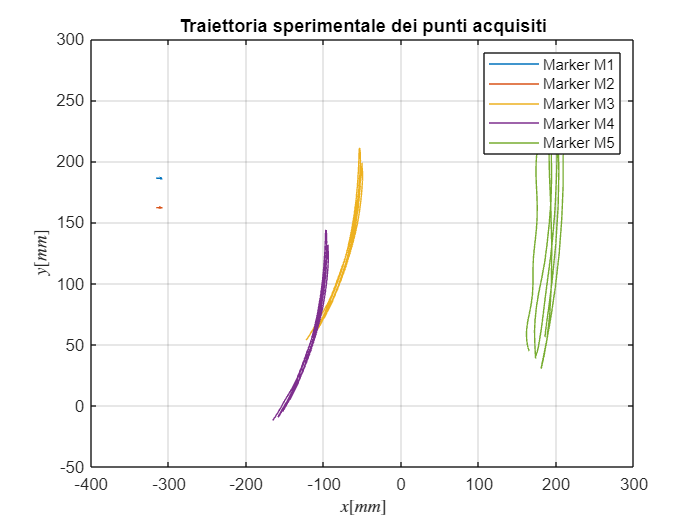

figure
plot(M(:,1),M(:,2))
hold on
plot(M2(:,1),M2(:,2))
hold on
plot(M(:,3),M(:,4))
hold on
plot(M(:,5),M(:,6))
hold on
plot(M(:,7),M(:,8))
grid on
title('Traiettoria sperimentale dei punti acquisiti')
legend('Marker M1','Marker M2','Marker M3','Marker M4','Marker M5')
xlabel('$x [mm]$','Interpreter','latex')
ylabel('$y [mm]$','Interpreter','latex')

Si può notare come i marker M1 ed M2 risultino, con un'ottima approssimazione, fermi. Nella realtà, infatti, tali marker sono stati applicati in corrispondenza delle due cerniere a cui è agganciato il supporto per il braccio, che risultano macroscopicamente fermi. I marker M3 ed M4 percorrono due archi di circonferenza centrati rispettivamente in corrispondenza dei marker M1 ed M2. La traiettoria del marker M5, invece, risulta approsimativamente un arco di circonferenza, ma è visibilmente diversa. Questo è dovuto al movimento effettivo che è stato svolto durante il campionamento. Si evince, quindi, che il soggetto non è stato in grado di mantenere perfettamente fermo l'avambraccio rispetto al braccio.

## STEP3.4 Posizione e traiettoria dei baricentri G1 e G2

Servendosi delle tabelle antropometriche, è possibile calcolare la posizione dei barecentri G1 e G2, realitivi rispettivamente alle aste M2M4 ed M4M5.

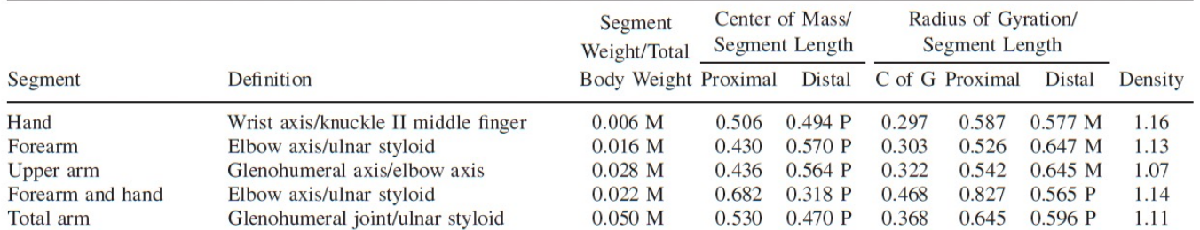

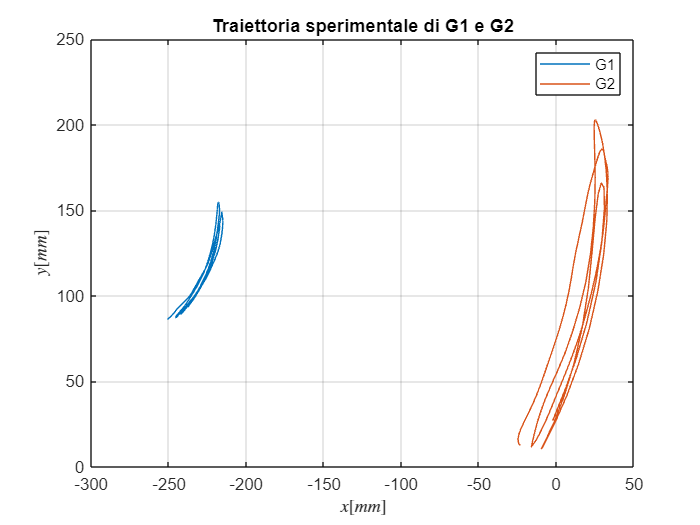

M2_G1=0.436*M2_M4;
G1_M4=M2_M4-M2_G1;
G1=[M(:,5)-(M(:,5)-M2(:,1))*(1-0.436) M(:,6)-(M(:,6)-M2(:,2))*(1-0.436)];

G2_M5=0.570*M4_M5;
M4_G2=M4_M5-G2_M5;
G2=[M(:,7)-0.570*(M(:,7)-M(:,5)) M(:,8)-0.570*(M(:,8)-M(:,6))];

figure
plot(G1(:,1),G1(:,2))
hold on
plot(G2(:,1),G2(:,2))
grid on
title('Traiettoria sperimentale di G1 e G2')
legend('G1','G2')
xlabel('$x [mm]$','Interpreter','latex')
ylabel('$y [mm]$','Interpreter','latex')

Si può notare come le traiettorie risultino simili, rispettivamente, alle traiettorie dei punti M4 ed M5, anche se ricalcano approssimativamente due archi di circonferenza con raggi inferiori, poichè i baricentri si trovano ad una distanza inferiore dal centro di rotazione rispetto ai due marker.

## STEP3.5 Range of motion della spalla

Per calcolare il range of motion della spalla si può definire l'angolo ($\vartheta$), che il segmento M2M4 (il braccio) forma con la verticale, istante per istante. Per effettuare questa operazione è possibile ricorrere al prodotto scalare:


$$\begin{array}{l}
\vec{\textrm{v1}} \cdot \vec{\textrm{v2}} =\left\lbrack \begin{array}{cc}
\textrm{x1} & \textrm{y1}
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\textrm{x2}\\
\textrm{y2}
\end{array}\right\rbrack =\textrm{x1x2}+\textrm{y1y2}\\
\vec{\textrm{v1}} \cdot \vec{\textrm{v2}} =\left|\vec{\textrm{v1}} \right|\left|\vec{\textrm{v2}} \right|\cos \left(\vartheta \right)\\
\cos \left(\vartheta \right)=\frac{\vec{\textrm{v1}} \cdot \vec{\textrm{v2}} }{\left|\vec{\textrm{v1}} \right|\left|\vec{\textrm{v2}} \right|}=\frac{\textrm{x1x2}+\textrm{y1y2}}{\left|\vec{\textrm{v1}} \right|\left|\vec{\textrm{v2}} \right|}\\
\vartheta =\cos^{-1} \left(\frac{\textrm{x1x2}+\textrm{y1y2}}{\left|\vec{\textrm{v1}} \right|\left|\vec{\textrm{v2}} \right|}\right)
\end{array}$$


Si selezionano infine i valori massimo e minimo di $\vartheta$ e se ne fa la differenza.

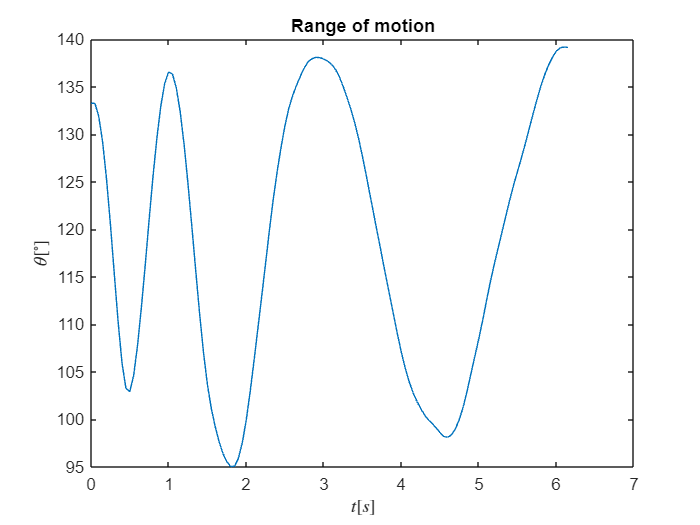

ny=[0 1]; %versore asse y
tmp=[M(:,5)-M2(:,1) M(:,6)-M2(:,2)];
for ii=1:size(M,1)
    ps=ny(1)*tmp(ii,1)+ny(2)*tmp(ii,2); %prodotto scalare tra i due vettori
    pm=(sqrt(ny(1).^2+ny(2).^2))*(sqrt(tmp(ii,1).^2+tmp(ii,2).^2)); %prodotto dei moduli
    teta(ii,1)=rad2deg(acos(ps/pm)); %formula inversa del prodotto scalare tra due vettori
end
ROM=[min(teta) max(teta)];
delta_ROM=ROM(2)-ROM(1);

figure
plot(time,teta)
xlabel('$t [s]$','Interpreter','latex')
ylabel('${\theta} [^{\circ}]$','Interpreter','latex')
title('Range of motion')

Plottando i valori di $\vartheta$ istante per istante, è possibile visualizzare l'andamento dell'angolo formato dal braccio con la verticale, nel tempo.

## STEP3.6 Velocità e accelerazione di M4

Poichè la velocità risulta essere la derivata della posizione e l'accelerazione la derivata della velocità, conoscendo la posizione del marker M4 per ogni istante di tempo è possibile ricavare i valori della velocità e dell'acelerazione di tale punto sfruttando la definizione di derivata:


$$\vec{v} =\frac{\mathrm{d}}{\mathrm{d}t}\vec{p} =\frac{p\left(t+1\right)-p\left(t\right)}{\textrm{dt}}$$



$$\vec{a} =\frac{\mathrm{d}}{\mathrm{d}t}\vec{v} =\frac{v\left(t+1\right)-v\left(t\right)}{\textrm{dt}}$$


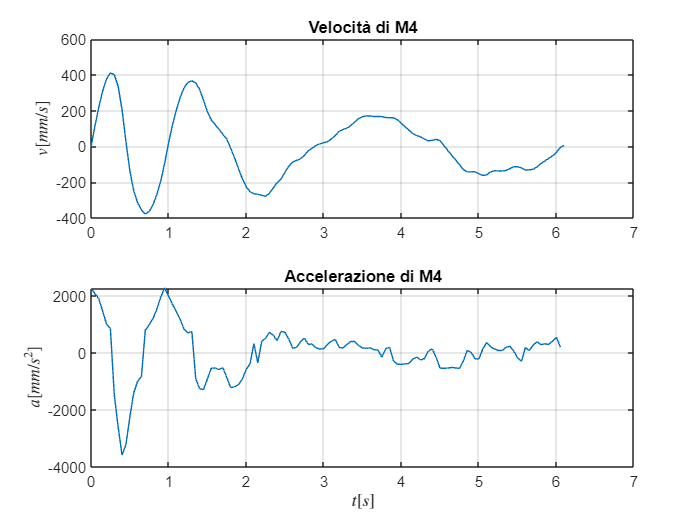

for ii=1:(size(M,1)-1)
    M4p(ii,1)=(M(ii+1,5)-M(ii,5))/f; %componente x
    M4p(ii,2)=(M(ii+1,6)-M(ii,6))/f; %componente y
    if M(ii+1,6)>M(ii,6)
        M4pm(ii,1)=sqrt(M4p(ii,1)^2+M4p(ii,2)^2); %modulo
    elseif M(ii+1,6)<M(ii,6)
        M4pm(ii,1)=-sqrt(M4p(ii,1)^2+M4p(ii,2)^2); %modulo
    end
end
for ii=1:(size(M4p,1)-1)
    M4pp(ii,1)=(M4p(ii+1,1)-M4p(ii,1))/f; %componente x
    M4pp(ii,2)=(M4p(ii+1,2)-M4p(ii,2))/f; %componente y
    if M4p(ii+1,2)>M4p(ii,2)
        M4ppm(ii,1)=sqrt(M4pp(ii,1)^2+M4pp(ii,2)^2); %modulo
    elseif M4p(ii+1,2)<M4p(ii,2)
        M4ppm(ii,1)=-sqrt(M4pp(ii,1)^2+M4pp(ii,2)^2); %modulo
    end
end
figure
subplot(211)
plot(time(1:end-1),M4pm)
grid on
ylabel('$v [mm/s]$','Interpreter','latex')
title('Velocità di M4')
hold on
subplot(212)
plot(time(1:end-2),M4ppm)
grid on
xlabel('$t [s]$','Interpreter','latex')
ylabel('$a [mm/s^2]$','Interpreter','latex')
title('Accelerazione di M4')

## STEP3.7 Risoluzione teorica del cinematismo

Conoscendo velocità e accelerazione del marker M4 è possibile risolvere il cinematismo mediante il metodo della chiusura cinematica.

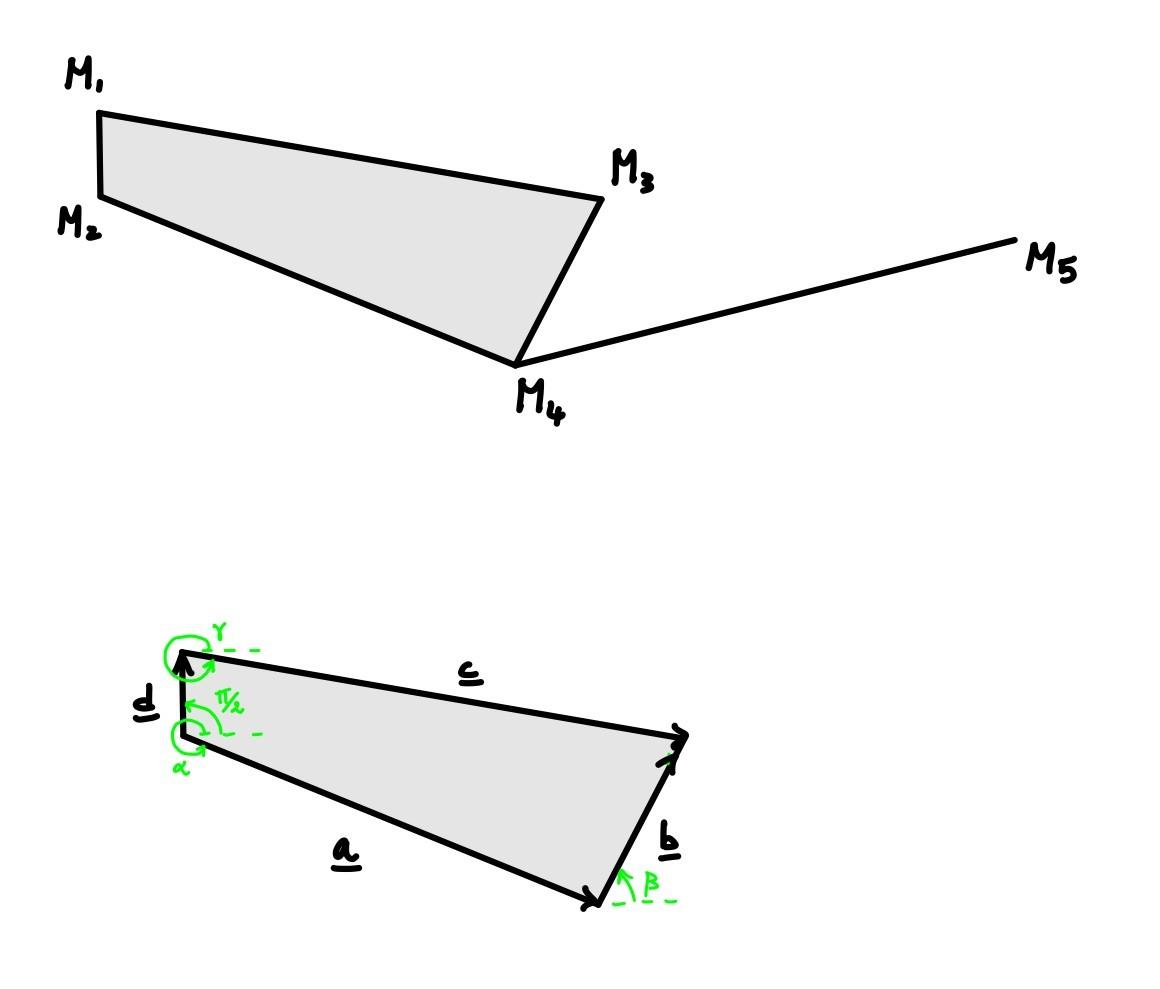

Innnzitutto è necessario calcolare le fasi $\alpha$, $\beta$, e $\gamma$per ciascuno atto di moto ed è possibile farlo sulla base di considerazioni geometriche e goniometriche.

Le grandezze rappresentate in figura sono:

- a = M2M4 costante

- b = M3M4 costante

- c = M1M3 costante

- d = M1M2 costante

- $\alpha$ variabile

- $\beta$ variabile

- $\gamma$ variabile

- $\delta =\frac{\pi }{2}$ costante

Successivamente è possibile ricavare la velocità angolare $\overset{\cdot }{\alpha}$ (velocità angolare dell'asta M2M4) mediante il rapporto tra velocità lineare e lunghezza del segmento considerato.

Di seguito si riportano i passaggi matematici che permettono di ricavare i sistemi risolutivi:

$\left\lbrace \begin{array}{ll}
a\;\cos \left(\alpha \right)+b\;\cos \left(\beta \right)=c\;\cos \left(\gamma \right)+d\;\cos \left(\delta \right) & \\
a\;\sin \left(\alpha \right)+b\;\sin \left(\beta \right)=c\;\sin \left(\gamma \right)+d\;\sin \left(\delta \right) & 
\end{array}\right.$, derivando si ottiene,

$\left\lbrace \begin{array}{ll}
-a\;\overset{\ldotp }{\alpha} \;\sin \left(\alpha \right)-b\;\overset{\ldotp }{\beta \;} \sin \left(\beta \right)=-c\;\overset{\ldotp }{\gamma \;} \sin \left(\gamma \right) & \\
a\;\overset{\ldotp }{\alpha} \;\cos \left(\alpha \right)+b\;\overset{\ldotp }{\beta} \;\cos \left(\beta \right)=c\;\overset{\ldotp }{\gamma} \;\cos \left(\gamma \right) & 
\end{array}\right.$  , derivando ancora una volta si ottiene,


$$\left\lbrace \begin{array}{ll}
-a\;\overset{\ldotp \ldotp }{\alpha} \;\sin \left(\alpha \right)-a\;{\overset{\ldotp }{\alpha} }^2 \cos \left(\alpha \right)-b\;\overset{\ldotp \ldotp }{\beta} \;\sin \left(\beta \right)-b\;{\overset{\ldotp }{\beta} }^2 \cos \left(\beta \right)=-c\;\overset{\ldotp \ldotp }{\gamma} \;\sin \left(\gamma \right)-c\;{\overset{\ldotp }{\gamma} }^2 \cos \left(\gamma \right) & \\
a\;\overset{\ldotp \ldotp }{\alpha} \;\cos \left(\alpha \right)-a\;{\overset{\ldotp }{\alpha} }^2 \sin \left(\alpha \right)+b\;\overset{\ldotp \ldotp }{\beta} \;\cos \left(\beta \right)-b\;{\overset{\ldotp }{\beta} }^2 \sin \left(\beta \right)=c\;\overset{\ldotp \ldotp }{\gamma} \;\cos \left(\gamma \right)-c\;{\overset{\ldotp }{\gamma} }^2 \sin \left(\gamma \right) & 
\end{array}\right.$$


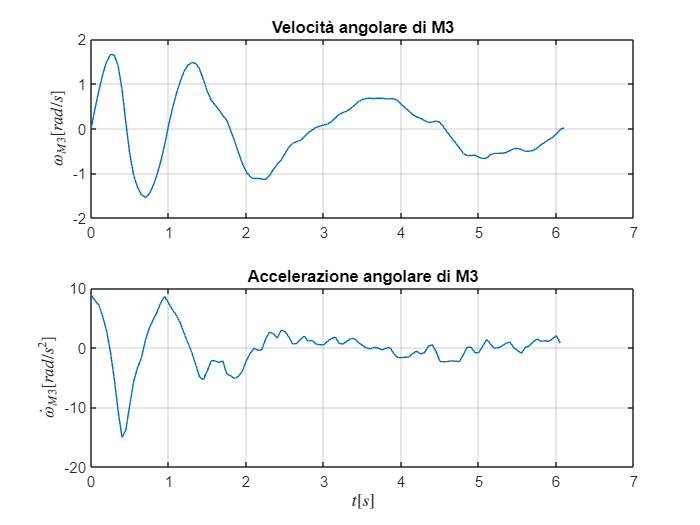

%Calcolo delle fasi dei vettori della chiusura cinematica
for ii=1:size(M,1)
    %alpha
    if M(ii,6)<M2(ii,2)
        alpha(ii,1)=360-atand((abs(M(ii,6)-M2(ii,2)))/(abs(M(ii,5)-M2(ii,1))));
    elseif M(ii,6)>M2(ii,2)
        alpha(ii,1)=atand((abs(M(ii,6)-M2(ii,2)))/(abs(M(ii,5)-M2(ii,1))));
    elseif M(ii,6)==M2(ii,2)
        alpha(ii,1)=0;
    end
    %gamma
    if M(ii,4)<M(ii,2)
        gamma(ii,1)=360-atand((abs(M(ii,4)-M(ii,2)))/(abs(M(ii,3)-M(ii,1))));
    elseif M(ii,4)>M(ii,2)
        gamma(ii,1)=atand((abs(M(ii,4)-M(ii,2)))/(abs(M(ii,3)-M(ii,1))));
    elseif M(ii,4)==M(ii,2)
        gamma(ii,1)=0;
    end
    %beta
    beta(ii,1)=atand((abs(M(ii,4)-M(ii,6)))/(abs(M(ii,3)-M(ii,5))));
end
a=M2_M4;
b=M3_M4;
c=M1_M3;

%Calcolo di velocità angolari del quadrilatero articolato tramite chiusura cinematica
for ii=1:length(M4pm)
    alphap(ii,1)=M4pm(ii)/M2_M4;
    x0=[a*alphap(ii)*sind(alpha(ii));
        -a*alphap(ii)*cosd(alpha(ii))];
    A=[c*sind(gamma(ii)) -b*sind(beta(ii));
        -c*cosd(gamma(ii)) b*cosd(beta(ii))];
    x=A\x0;
    gammap(ii,1)=x(1);
    betap(ii,1)=x(2);
end

%Calcolo di accelerazioni angolari del quadrilatero articolato tramite chiusura cinematica
for ii=1:length(M4pp)
    alphapp(ii,1)=(alphap(ii+1)-alphap(ii))/f;
    x0=[a*alphapp(ii)*sind(alpha(ii))+a*alphap(ii).^2*cosd(alpha(ii))+b*betap(ii).^2*cosd(beta(ii))-c*gammap(ii).^2*cosd(gamma(ii));
        -a*alphapp(ii)*cosd(alpha(ii))+a*alphap(ii).^2*sind(alpha(ii))+b*betap(ii).^2*sind(beta(ii))-c*gammap(ii).^2*sind(gamma(ii))];
    A=[c*sind(gamma(ii)) -b*sind(beta(ii));
        -c*cosd(gamma(ii)) b*cosd(beta(ii))];
    x=A\x0;
    gammapp(ii,1)=x(1);
    betapp(ii,1)=x(2);
end

%Rappresentazione di velocità e accelerazione angolari di M3
figure
subplot(211)
plot(time(1:end-1),gammap(:))
grid on
title('Velocità angolare di M3')
ylabel('$\omega_{M3} [{rad}/{s}]$','Interpreter','latex')
subplot(212)
plot(time(1:end-2),gammapp(:))
grid on
title('Accelerazione angolare di M3')
ylabel('$\dot{\omega}_{M3} [{rad}/{s^{2}}]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')

Poiché braccio e avambraccio si muovono solidalmente, la velocità e l'accelerazione angolare dei due tratti sono le medesime.

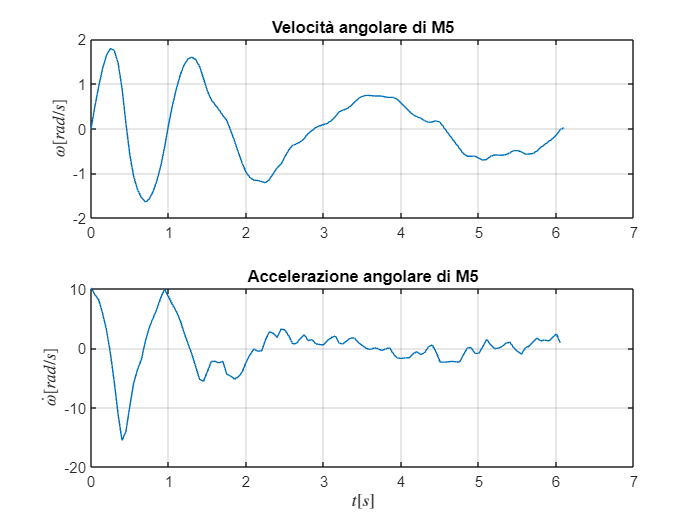

%Poiché braccio e avambraccio si muovono solidalmente, la velocità e
%l'accelerazione angolare dei due tratti sono le medesime (alphap e alphapp)

%Rappresentazione di velocità e accelerazione angolari di M5
figure
subplot(211)
plot(time(1:end-1),alphap(:))
grid on
title('Velocità angolare di M5')
ylabel('$\omega [{rad}/{s}]$','Interpreter','latex')
subplot(212)
plot(time(1:end-2),alphapp(:))
grid on
title('Accelerazione angolare di M5')
ylabel('$\dot{\omega} [{rad}/{s}]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')

## STEP3.8 Confronto teorico-sperimentale di velocità e accelerazione angolari di M5

Conoscendo velocità e accelerazione di M5 è possibile ricavare la velocità e l'accelerazione angolare di M5 (rispetto al suo centro di rotazione M2) mediante il rapporto tra velocità lineare e lunghezza del segmento M2M5 e derivando la velocità trovata per ricavare l'accelerazione.

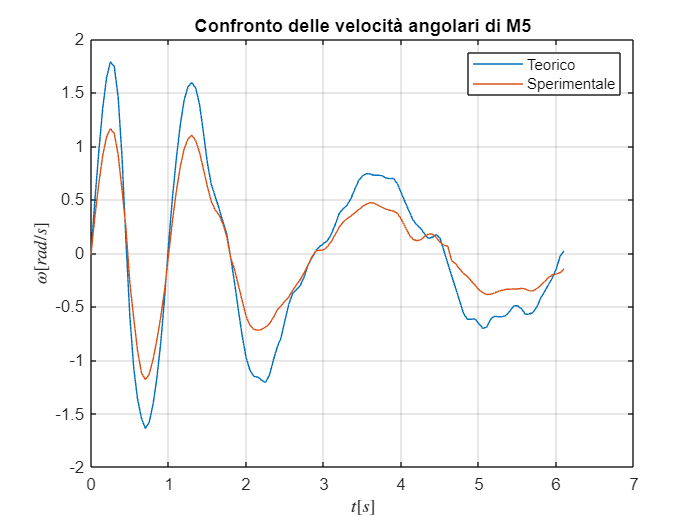

%Calcolo della velocità di M5 dai dati sperimentali
for ii=1:(size(M,1)-1)
    M5p(ii,1)=(M(ii+1,7)-M(ii,7))/f; %componente x
    M5p(ii,2)=(M(ii+1,8)-M(ii,8))/f; %componente y
    if M(ii+1,8)>M(ii,8)
        M5pm(ii,1)=sqrt(M5p(ii,1)^2+M5p(ii,2)^2); %modulo
    elseif M(ii+1,8)<M(ii,8)
        M5pm(ii,1)=-sqrt(M5p(ii,1)^2+M5p(ii,2)^2); %modulo
    end
end
%Calcolo della velocità angolare di M5 dai dati sperimentali
for ii=1:length(M5p)
    wM5(ii,1)=M5pm(ii)/M2_M5;
end
%Calcolo dell'accelerazione angolare di M5 dai dati sperimentali
for ii=1:(length(M5p)-1)
    wpM5(ii,1)=(wM5(ii+1)-wM5(ii))/f;
end

%Confronto grafico
figure
plot(time(1:end-1),alphap(:))
hold on
plot(time(1:end-1),wM5(:))
grid on
title('Confronto delle velocità angolari di M5')
legend('Teorico','Sperimentale')
ylabel('$\omega [{rad}/{s}]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')

Dalla figura si può vedere come le due curve presentano un andamento simile, anche se presentano due ampiezze diverse. Queste differenze sono dovute all'errore dovuto all'incapacità del soggetto di mantenere perfettamente fermo l'avambraccio rispetto al braccio durante il campionamento dei dati.

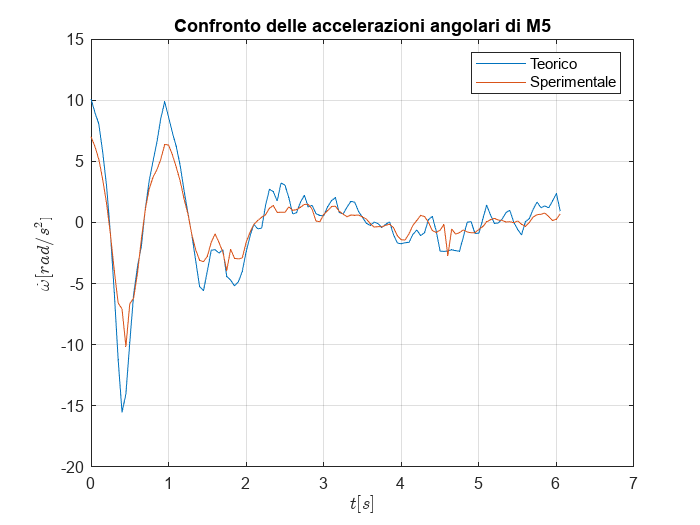

figure
plot(time(1:end-2),alphapp(:))
hold on
plot(time(1:end-2),wpM5(:))
grid on
title('Confronto delle accelerazioni angolari di M5')
legend('Teorico','Sperimentale')
ylabel('$\dot{\omega} [{rad}/{s^{2}}]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')

Le stesse considerazione fatte per le velocità angolari risultano valide anche per le accelerazioni.

## STEP4.0 Dati dinamica

Dalle tabelle antropometriche è possibile ricavare le masse di braccio, avambraccio e mano e i raggi giratori di braccio (segmento M2M4) e avmbraccio (segmento M4M5), che servono per calcolare i momenti d'inerzia degli stessi. 

uw=0.028*m; %upper arm weight
fw=0.016*m; %forearm weight
hw=0.006*m; %hand weight
rG1=0.322*M2_M4; %upper arm's radius of giration 
rG2=0.303*M4_M5; %forearm's radius of giration
JG1=uw*(rG1^2/1000000);
JG2=fw*(rG2^2/1000000);
tmp=[180 0];
for ii=1:length(teta)
    if abs(90-teta(ii))<abs(90-tmp(1)) && alphap(ii)>0
        tmp=[teta(ii) ii];
    end
end
v_M4(1,1)=M4p(tmp(2),1); %componente x
v_M4(1,2)=M4p(tmp(2),2); %componente y
v_M4(1,3)=M4pm(tmp(2),1); %modulo
a_M4(1,1)=M4pp(tmp(2),1); %componente x
a_M4(1,2)=M4pp(tmp(2),2); %componente y
a_M4(1,3)=M4ppm(tmp(2),1); %modulo
w1=alphap(tmp(2));
w2=w1;
w1p=alphapp(tmp(2));
w2p=w1p;

## STEP4.1 Vettore velocità di G1 e G2

Per disegnare i vettori velocità dei baricentri G1 e G2, conoscendo le posizioni dei due punti per ogni istante di tempo, è possibile calcolare le componenti dei due vettori tramite la definizione di derivata (come si è fatto in precedenza per altri punti) e poi plottare i risultati ottenuti.

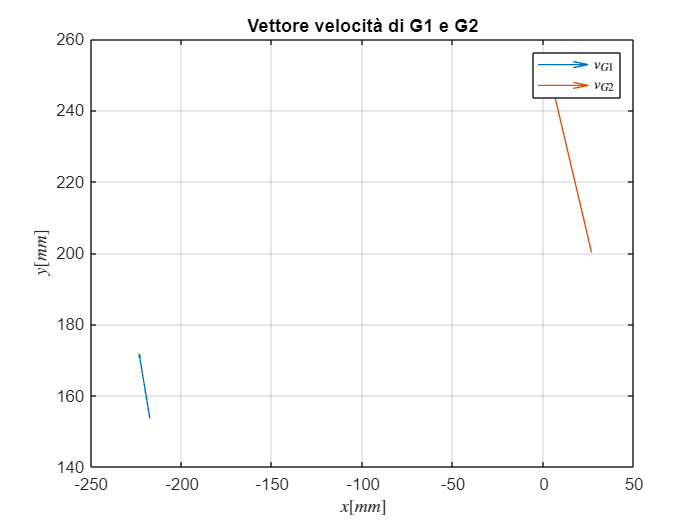

v_G1(1)=(G1(tmp(2)+1,1)-G1(tmp(2),1))/f;
v_G1(2)=(G1(tmp(2)+1,2)-G1(tmp(2),2))/f;
if G1(tmp(2)+1,2)>G1(tmp(2),2)
    v_G1(3)=sqrt(v_G1(1)^2+v_G1(2)^2);
elseif G1(tmp(2)+1,2)<G1(tmp(2),2)
    v_G1(3)=-sqrt(v_G1(1)^2+v_G1(2)^2);
end
v_G2(1)=(G2(tmp(2)+1,1)-G2(tmp(2),1))/f;
v_G2(2)=(G2(tmp(2)+1,2)-G2(tmp(2),2))/f;
if G2(tmp(2)+1,2)>G2(tmp(2),2)
    v_G2(3)=sqrt(v_G2(1)^2+v_G2(2)^2);
elseif G2(tmp(2)+1,2)<G2(tmp(2),2)
    v_G2(3)=-sqrt(v_G2(1)^2+v_G2(2)^2);
end
figure
quiver(G1(tmp(2),1),G1(tmp(2),2),v_G1(1),v_G1(2),0);
hold on
quiver(G2(tmp(2),1),G2(tmp(2),2),v_G2(1),v_G2(2),0);
grid on
title('Vettore velocità di G1 e G2')
legend('${v}_{G1}$','${v}_{G2}$','Interpreter','latex')
xlabel('$x [mm]$','Interpreter','latex')
ylabel('$y [mm]$','Interpreter','latex')

## STEP4.2 Vettore accelerazione di G1 e G2

Per i vettori accelerazione dei baricentri si può procedere in modo analogo ai vettori velocità.

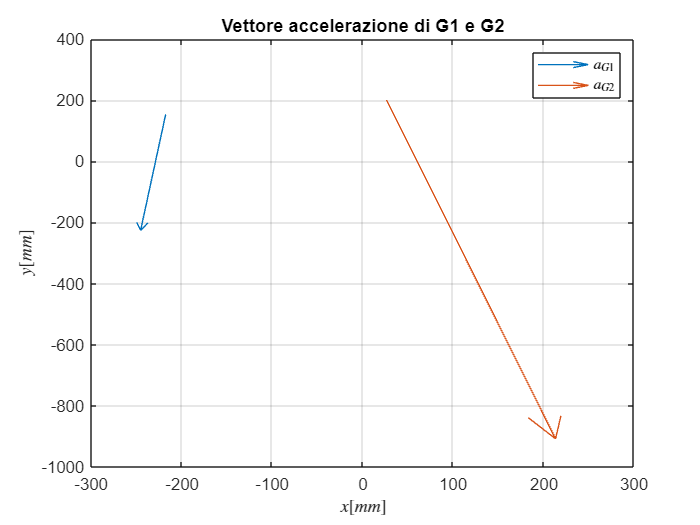

a_G1(1)=(((G1(tmp(2)+2,1)-G1(tmp(2)+1,1))/f)-v_G1(1))/f;
a_G1(2)=(((G1(tmp(2)+2,2)-G1(tmp(2)+1,2))/f)-v_G1(2))/f;
if ((G1(tmp(2)+2,2)-G1(tmp(2)+1,2))/f)>v_G1(2)
    a_G1(3)=sqrt(a_G1(1)^2+a_G1(2)^2);
elseif ((G1(tmp(2)+2,2)-G1(tmp(2)+1,2))/f)<v_G1(2)
    a_G1(3)=-sqrt(a_G1(1)^2+a_G1(2)^2);
end
a_G2(1)=(((G2(tmp(2)+2,1)-G2(tmp(2)+1,1))/f)-v_G2(1))/f;
a_G2(2)=(((G2(tmp(2)+2,2)-G2(tmp(2)+1,2))/f)-v_G2(2))/f;
if ((G2(tmp(2)+2,2)-G2(tmp(2)+1,2))/f)>v_G2(2)
    a_G2(3)=sqrt(a_G2(1)^2+a_G2(2)^2);
elseif ((G2(tmp(2)+2,2)-G2(tmp(2)+1,2))/f)<v_G2(2)
    a_G2(3)=-sqrt(a_G2(1)^2+a_G2(2)^2);
end
figure
quiver(G1(tmp(2),1),G1(tmp(2),2),a_G1(1),a_G1(2),0);
hold on
quiver(G2(tmp(2),1),G2(tmp(2),2),a_G2(1),a_G2(2),0);
grid on
title('Vettore accelerazione di G1 e G2')
legend('${a}_{G1}$','${a}_{G2}$','Interpreter','latex')
xlabel('$x [mm]$','Interpreter','latex')
ylabel('$y [mm]$','Interpreter','latex')

## STEP4.3 Coppia muscolare con supporto antigravitario

Per calcolare le coppie muscolari esercitate dai muscoli flessori ($C_f$) e dai muscoli estensori ($C_e$) è possibile ricorrere all'equilibrio tra le forze e tra i momenti.

Le forze, i momenti e le reazioni vincolari che agiscono sui vari tratti dell'esoscheletro sono riportate nello schema seguente (non sono presenti le forze peso perchè compensate dal supporto antigravitario):

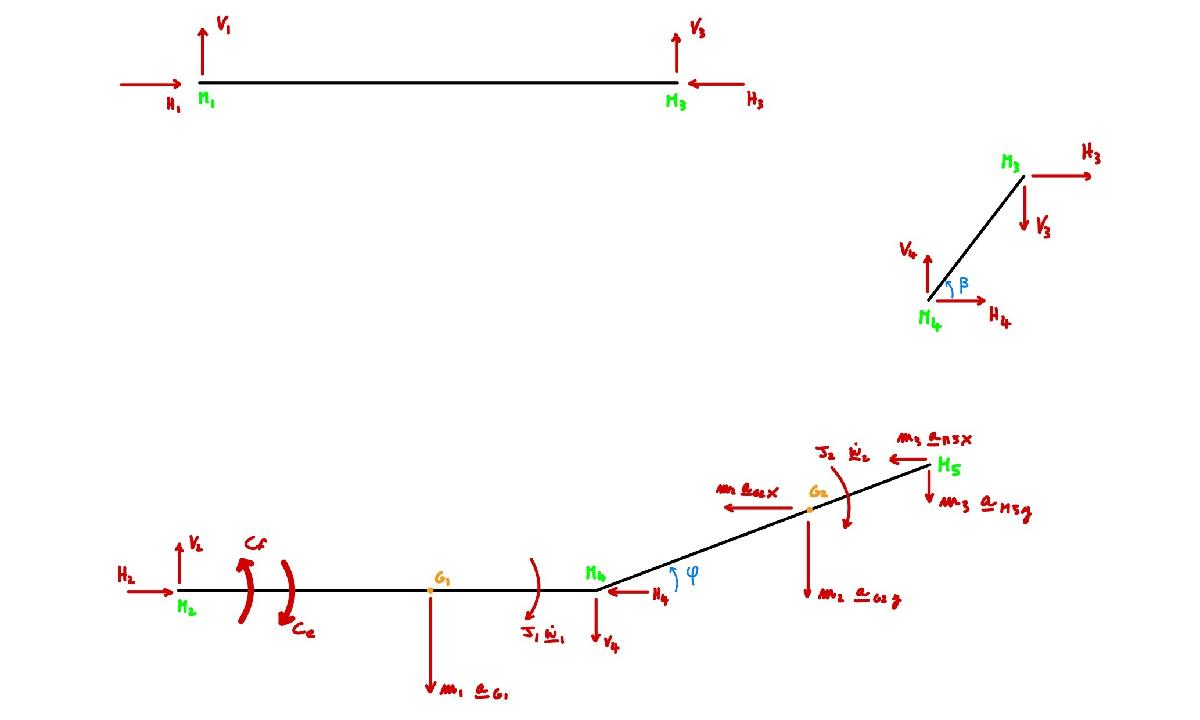

Applicando l'equilibrio tra forze e momenti si ottengono i seguenti tre sistemi:


$${\left\{\begin{array}{c}
V1+V3=0\\
H1-H3=0\\
M1M3∙V3=0
\end{array}\right)}$$



$${\left\{\begin{array}{c}
V4-\textrm{V3}=0\\
H3+H4=0\\
-M3M4∙\sin {\left(\beta \right)}∙\textrm{H3}-M3M4∙cos\left(\beta \right)∙\textrm{V3}=0
\end{array}\right)}$$



$${\left\{\begin{array}{c}
\textrm{V2}-\textrm{V4}-m_1 \cdot \vec{a_{\textrm{G1}} } -m_2 \cdot \vec{a_{\textrm{G2y}} } -m_3 \cdot \vec{a_{\textrm{M5y}} } =0\\
\textrm{H2}-\textrm{H4}-m_2 \cdot \vec{a_{\textrm{G2x}} } -m_3 \cdot \vec{a_{\textrm{M5x}} } =0\\
C_f -C_e -J_1 \vec{{\dot{w} }_1 } -J_2 \vec{{\dot{w} }_2 } -\textrm{M2M4}\cdot \textrm{V2}+m_1 \cdot \vec{a_{\textrm{G1}} } \cdot \textrm{G1M4}-m_2 \cdot \vec{a_{\textrm{G2y}} } \cdot \textrm{M4G2}\cdot \cos \left(\beta \right)+\\
+m_2 \cdot \vec{a_{\textrm{G2x}} } \cdot \textrm{M4G2}\cdot \sin \left(\beta \right)-m_3 \cdot \vec{a_{\textrm{M5y}} } \cdot \textrm{M4M5}\cdot \cos \left(\beta \right)+m_3 \cdot \vec{a_{\textrm{M5x}} } \cdot \textrm{M4M5}\cdot \sin \left(\beta \right)=0
\end{array}\right)}$$


A queste nove euquazioni si aggiunge la seguente equazione:


$$C_e =\frac{1}{10}C_f$$


%[H1 V1 H2 V2 H3 V3 H4 V4 Cf Ce]
g=0;
M4_G1=M2_M4-M2_G1;
phi_tmp=atand((M(tmp(2),8)-M(tmp(2),6))/(M(tmp(2),7)-M(tmp(2),5)));
phi=abs(phi_tmp);
eta=beta(tmp(2));

v_M5(1)=(M(tmp(2)+1,7)-M(tmp(2),7))/f;
v_M5(2)=(M(tmp(2)+1,8)-M(tmp(2),8))/f;
a_M5(1)=(((M(tmp(2)+2,7)-M(tmp(2)+1,7))/f)-v_M5(1))/f;
a_M5(2)=(((M(tmp(2)+2,8)-M(tmp(2)+1,8))/f)-v_M5(2))/f;

cf=0.1;
ce=1;
xx0=[0;
     0;
     0;
     0;
     0;
     0;
     (uw+fw+hw)*g+uw*(a_G1(2)/1000)+fw*(a_G2(2)/1000)+hw*(a_M5(2)/1000);
     fw*(a_G2(1)/1000)+hw*(a_M5(1)/1000);
     -uw*(G1_M4/1000)*(g+(a_G1(2)/1000))-fw*(M4_G2/1000)*sind(phi)*(a_G2(1)/1000)+...
     fw*(M4_G2/1000)*cosd(phi)*(g+(a_G2(2)/1000))-hw*(M4_M5/1000)*sind(phi)*(a_M5(1)/1000)+...
     hw*(M4_M5/1000)*cosd(phi)*(g+(a_M5(2)/1000))+(JG1+JG2)*w1p; %N.B.: w1=w2
     0];
AA=[0 1 0 0 0 1 0 0 0 0;
    1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 -1 0 1 0 0;
    0 0 0 0 1 0 1 0 0 0;
    0 0 0 0 -((M3_M4/1000)*sind(eta)) -((M3_M4/1000)*cosd(eta)) 0 0 0 0;
    0 0 0 1 0 0 0 -1 0 0;
    0 0 1 0 0 0 -1 0 0 0;
    0 0 0 -(M2_M4/1000) 0 0 0 0 1 -1;
    0 0 0 0 0 0 0 0 -cf ce];
xx=AA\xx0;
Cf=xx(9)

Cf = -0.9523

Ce=xx(10)

Ce = -0.0952

È possibile notare che i moduli delle due coppie risultano essere piccoli, infatti il supporto antigravitario elimina la gravità, che costituisce la componente principale da vinciere per il sollevamento del braccio.

Un altro risultato rilevante è il segno delle due coppie, che risulta essere negativo. Questo risultato è apparentemente in contrasto con la fisica del movimento e, in parte, lo è, poichè i muscoli antagonisti, contraendosi, generano le coppie sempre negli stessi versi (quelli indicati in figura). Questo risultato può essere spiegato riflettendo sul verso delle velocità e delle accelerazioni. Nell'atto di moto considerato, infatti, il braccio risulta essere in salita, infatti le velocità sono rivolte verso l'alto (come si evince dalla rappresentazione dei vettori velocità dei baricentri), ma le accelerazioni sono rivolte verso il basso (come si evince dalla rappresentazione dei vettori accelerazione dei baricentri), ciò significa che si ha un moto decelerato. In queste condizioni, poichè la gravità è completamente bilanciata dal supporto antigravitario, sono i muscoli stessi ad opporsi al moto, generando un contributo totale nel verso opposto a quello del moto (da qui il segno meno). Nella realtà saranno quindi i muscoli estensori a fornire un contributo maggiore rispetto a quelli flessori. Se si considerasse un contributo normalizzato dei muscoli flessori pari al 10% dei muscoli estensori (caso opposto a quello consideranto nello svolgimento del progetto), infatti, le due coppie risulterebbero avere medisimi moduli ma versi opposti (segni positivi).

## STEP4.4 Coppia muscolare senza supporto antigravitario

In assenza del supporto antigravitario sono è necessario considerare anche le forze peso dei vari tratti:

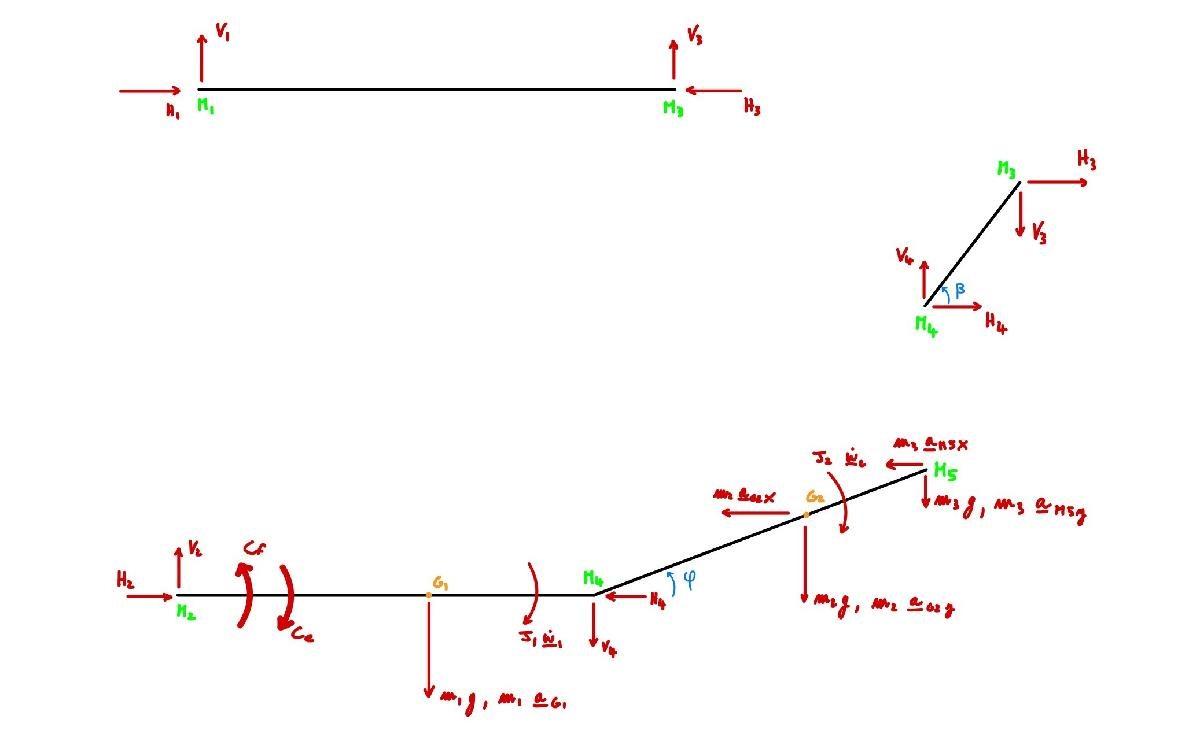

Applicando l'equilibrio tra forze e momenti si ottengono gli stessi tre sistemi ottenuti precedentemente completi delle forze peso:


$${\left\{\begin{array}{c}
V1+V3=0\\
H1-H3=0\\
M1M3∙V3=0
\end{array}\right)}$$



$${\left\{\begin{array}{c}
V4-\textrm{V3}=0\\
H3+H4=0\\
-M3M4∙\sin {\left(\beta \right)}∙\textrm{H3}-M3M4∙cos\left(\beta \right)∙\textrm{V3}=0
\end{array}\right)}$$



$${\left\{\begin{array}{c}
\textrm{V2}-\textrm{V4}-\left(m_1 +m_2 +m_3 \right)\cdot g-m_1 \cdot \vec{a_{\textrm{G1}} } -m_2 \cdot \vec{a_{\textrm{G2y}} } -m_3 \cdot \vec{a_{\textrm{M5y}} } =0\\
\textrm{H2}-\textrm{H4}-m_2 \cdot \vec{a_{\textrm{G2x}} } -m_3 \cdot \vec{a_{\textrm{M5x}} } =0\\
C_f -C_e -J_1 \vec{{\dot{w} }_1 } -J_2 \vec{{\dot{w} }_2 } -\textrm{M2M4}\cdot \textrm{V2}+m_1 \left(g+\vec{a_{\textrm{G1}} } \right)\cdot \textrm{G1M4}-m_2 \left(g+\vec{a_{\textrm{G2y}} } \right)\cdot \textrm{M4G2}\cdot \cos \left(\beta \right)+\\
+m_2 \cdot \vec{a_{\textrm{G2x}} } \cdot \textrm{M4G2}\cdot \sin \left(\beta \right)-m_3 \cdot \left(g+\vec{a_{\textrm{M5y}} } \right)\cdot \textrm{M4M5}\cdot \cos \left(\beta \right)+m_3 \cdot \vec{a_{\textrm{M5x}} } \cdot \textrm{M4M5}\cdot \sin \left(\beta \right)=0
\end{array}\right)}$$


A queste nove euquazioni si aggiunge la seguente equazione:


$$C_e =\frac{1}{10}C_f$$


%[H1 V1 H2 V2 H3 V3 H4 V4 Cf Ce]
g=9.81;
xx0=[0;
     0;
     0;
     0;
     0;
     0;
     (uw+fw+hw)*g+uw*(a_G1(2)/1000)+fw*(a_G2(2)/1000)+hw*(a_M5(2)/1000);
     fw*(a_G2(1)/1000)+hw*(a_M5(1)/1000);
     -uw*(G1_M4/1000)*(g+(a_G1(2)/1000))-fw*(M4_G2/1000)*sind(phi)*(a_G2(1)/1000)+...
     fw*(M4_G2/1000)*cosd(phi)*(g+(a_G2(2)/1000))-hw*(M4_M5/1000)*sind(phi)*(a_M5(1)/1000)+...
     hw*(M4_M5/1000)*cosd(phi)*(g+(a_M5(2)/1000))+(JG1+JG2)*w1p; %N.B.: w1=w2
     0];
AA=[0 1 0 0 0 1 0 0 0 0;
    1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 -1 0 1 0 0;
    0 0 0 0 1 0 1 0 0 0;
    0 0 0 0 -((M3_M4/1000)*sind(eta)) -((M3_M4/1000)*cosd(eta)) 0 0 0 0;
    0 0 0 1 0 0 0 -1 0 0;
    0 0 1 0 0 0 -1 0 0 0;
    0 0 0 -(M2_M4/1000) 0 0 0 0 1 -1;
    0 0 0 0 0 0 0 0 -cf ce];
xx=AA\xx0;
Cf_g=xx(9)

Cf_g = 6.8792

Ce_g=xx(10)

Ce_g = 0.6879

Le coppie calcolate senza il supporto antigravitario risultano essere circa sette volte maggiori rispetto a quelle calcolate precedentemente e positive. In queste condizioni, infatti, i muscoli dovranno fare uno sforzo maggiore per compiere lo stesso movimento. Il segno risulta essere, giustamente, positivo, poichè in questo caso è presente la gravità, che si oppone naturalmente al moto del braccio in salita, quindi ai muscoli basterà generare delle coppie più piccole in modulo per dare vita ad una decelerazione.

## STEP4.5 Reazioni vincolari in M1 e M2 con aggancio alla carrozzina

Per calcolare le reazioni vincolari in M1 ed M2, considerando l'esoscheletro non più a terra, ma agganciato ad una carrozzina, è possibile sfruttare gli stessi sistemi ricavati allo step precedente utilizzando i dati opportunamente ridefiniti.

%[H1 V1 H2 V2 H3 V3 H4 V4 Cf Ce]
uw=uw+0.2*uw; %upper arm weight
fw=fw+0.2*fw; %forearm weight
JG1=uw*(rG1^2/1000000);
JG2=fw*(rG2^2/1000000);
xx0=[0;
     0;
     0;
     0;
     0;
     0;
     (uw+fw+hw)*g+uw*(a_G1(2)/1000)+fw*(a_G2(2)/1000)+hw*(a_M5(2)/1000);
     fw*(a_G2(1)/1000)+hw*(a_M5(1)/1000);
     -uw*(G1_M4/1000)*(g+(a_G1(2)/1000))-fw*(M4_G2/1000)*sind(phi)*(a_G2(1)/1000)+...
     fw*(M4_G2/1000)*cosd(phi)*(g+(a_G2(2)/1000))-hw*(M4_M5/1000)*sind(phi)*(a_M5(1)/1000)+...
     hw*(M4_M5/1000)*cosd(phi)*(g+(a_M5(2)/1000))+(JG1+JG2)*w1p; %N.B.: w1=w2
     0];
AA=[0 1 0 0 0 1 0 0 0 0;
    1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 -1 0 1 0 0;
    0 0 0 0 1 0 1 0 0 0;
    0 0 0 0 -((M3_M4/1000)*sind(eta)) -((M3_M4/1000)*cosd(eta)) 0 0 0 0;
    0 0 0 1 0 0 0 -1 0 0;
    0 0 1 0 0 0 -1 0 0 0;
    0 0 0 -(M2_M4/1000) 0 0 0 0 1 -1;
    0 0 0 0 0 0 0 0 -cf ce];
xx=AA\xx0;
H1_s1=xx(1)

H1_s1 = 0

V1_s1=xx(2)

V1_s1 = 0

H2_s1=xx(3)

H2_s1 = 0.3908

V2_s1=xx(4)

V2_s1 = 32.5868

## STEP4.6 Reazioni vincolari in M1 e M2 con aggancio alla carrozzina e con soggetto diverso

Per calcolare le reazioni vincolari in M1 ed M2, considerando l'esoscheletro non più a terra, ma agganciato ad una carrozzina, ed un soggetto diverso, è possibile sfruttare gli stessi sistemi ricavati allo step precedente utilizzando i dati opportunamente ridefiniti.

m=90; %[Kg]
uw=0.028*m+0.2*(0.028*m); %upper arm weight con soggetto diverso e aggancio
fw=0.016*m+0.2*(0.016*m); %forearm weight con soggetto diverso e aggancio
hw=0.006*m; %hand weight con soggetto diverso
JG1=uw*(rG1^2/1000000);
JG2=fw*(rG2^2/1000000);
%[H1 V1 H2 V2 H3 V3 H4 V4 Cf Ce]
xx0=[0;
     0;
     0;
     0;
     0;
     0;
     (uw+fw+hw)*g+uw*(a_G1(2)/1000)+fw*(a_G2(2)/1000)+hw*(a_M5(2)/1000);
     fw*(a_G2(1)/1000)+hw*(a_M5(1)/1000);
     -uw*(G1_M4/1000)*(g+(a_G1(2)/1000))-fw*(M4_G2/1000)*sind(phi)*(a_G2(1)/1000)+...
     fw*(M4_G2/1000)*cosd(phi)*(g+(a_G2(2)/1000))-hw*(M4_M5/1000)*sind(phi)*(a_M5(1)/1000)+...
     hw*(M4_M5/1000)*cosd(phi)*(g+(a_M5(2)/1000))+(JG1+JG2)*w1p; %N.B.: w1=w2
     0];
AA=[0 1 0 0 0 1 0 0 0 0;
    1 0 0 0 -1 0 0 0 0 0;
    0 0 0 0 0 1 0 0 0 0;
    0 0 0 0 0 -1 0 1 0 0;
    0 0 0 0 1 0 1 0 0 0;
    0 0 0 0 -((M3_M4/1000)*sind(eta)) -((M3_M4/1000)*cosd(eta)) 0 0 0 0;
    0 0 0 1 0 0 0 -1 0 0;
    0 0 1 0 0 0 -1 0 0 0;
    0 0 0 -(M2_M4/1000) 0 0 0 0 1 -1;
    0 0 0 0 0 0 0 0 -cf ce];
xx=AA\xx0;
H1_s2=xx(1)

H1_s2 = 0

V1_s2=xx(2)

V1_s2 = 0

H2_s2=xx(3)

H2_s2 = 0.5766

V2_s2=xx(4)

V2_s2 = 48.0789

## STEP5.0 Dati vibrazioni

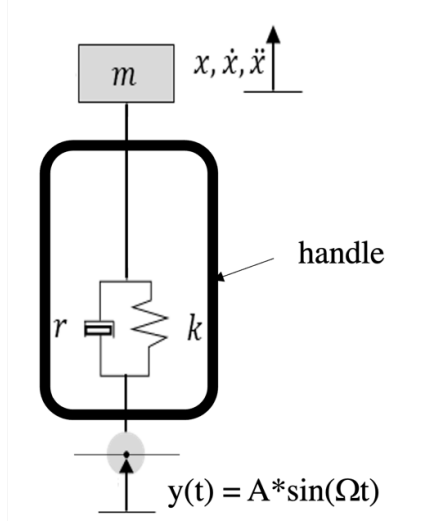

P=1;
r=500; %[Ns/m]
k=1e7/(P+1); %[N/m]
A=0.005; %[m]
W=P*1000; %[rad/s]
x0=0.1; %posizione iniziale
v0=0; %velocità iniziale
t=[0:0.00001:0.05];
g=9.81;
hw=0.006*61;

 L'allungamento e la velocità di allungamento della molla risultano essere:


$$\Delta l=x-y$$



$$\dot{\Delta l} =\dot{x} -\dot{y}$$


È possibile ricavare l'equazione di moto scrivendo l'equazione del bilancio di potenze:


$$\frac{\mathrm{d}}{\mathrm{d}t}E_c =m\dot{x} \ddot{x}$$



$$W_{\textrm{el}} =-k\cdot \Delta l\cdot \dot{x} =-kx\dot{x} +ky\dot{x}$$



$$W_{\textrm{smorz}} =-r\cdot \dot{\Delta l} \cdot \dot{x} =-r{\dot{x} }^2 +r\dot{y} \dot{x}$$



$$\frac{\mathrm{d}}{\mathrm{d}t}E_c =W_{\textrm{el}} +W_{\textrm{smorz}} \Longrightarrow m\ddot{x} +r\dot{x} +\textrm{kx}=\textrm{ky}+r\dot{y} \longrightarrow \left(\textrm{equazione}\;\textrm{di}\;\textrm{moto}\right)$$


## STEP5.1 Frequenza propria, smorzamento adimensionale e risposta libera

L'equazione di moto che descrive la risposta libera non smorzata del sistema si ricava azzerando il contibuto della forzante $\left(y=0\;e\;\dot{y} =0\right)$ e lo smorzamento $\left(r=0\right)$:


$$m\ddot{x} +\textrm{kx}=0$$



$$x\left(t\right)=C\cdot \cos \left(\omega_n t+\psi \right)$$


dove $C$ e $\psi$ sono date dalle condizioni iniziali:


$$\left\lbrace \begin{array}{ll}
x_0 =C\cdot \cos \left(\psi \right) & \\
v_0 =-\omega_n C\cdot \sin \left(\psi \right) & 
\end{array}\right.$$

$$\Longrightarrow \left\lbrace \begin{array}{ll}
\tan \left(\psi \right)=-\frac{v_0 }{x_0 }\frac{1}{w_n } & \\
C=\frac{x_0 }{\cos \left(\psi \right)} & 
\end{array}\right.$$


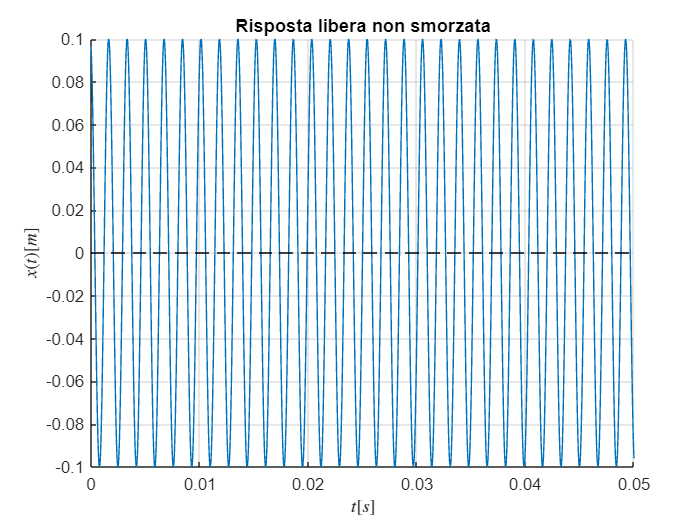

wn=sqrt(k/hw);
psi=atan(-v0/(wn*x0));
C=x0/cos(psi);
x=C*cos(wn*t+phi);
x_eq=-hw*g/k;
figure
hold on
plot(t,x+x_eq)
plot([0 t(end)],[x_eq x_eq],'k--')
grid on
ylabel('$x(t) [m]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')
title('Risposta libera non smorzata')

L'equazione di moto che descrive la risposta libera smorzata del sistema si ricava azzerando il contibuto della forzante $\left(y=0\;e\;\dot{y} =0\right)$:


$$m\ddot{x} +r\dot{x} +\textrm{kx}=0$$



$$\begin{array}{l}
x_d \left(t\right)=e^{-\alpha t} C_d \cdot \cos \left(\omega_d t+\psi_d \right)\\
\alpha =h\omega_n \\
h=\frac{r}{2mw_n }\\
\omega_d =\omega_n \sqrt{1-h^2 }
\end{array}$$


dove $C_d$e $\psi_d$ sono date dalle condizioni iniziali:


$$\left\lbrace \begin{array}{ll}
x_0 =C_d \cdot \cos \left(\psi_d \right) & \\
v_0 =-\omega_d C_d \cdot \sin \left(\psi_d \right) & 
\end{array}\right.$$

$$\Longrightarrow \left\lbrace \begin{array}{ll}
\tan \left(\psi_d \right)=-\frac{v_0 }{x_0 }\frac{1}{w_d } & \\
C_d =\frac{x_0 }{\cos \left(\psi \right)} & 
\end{array}\right.$$


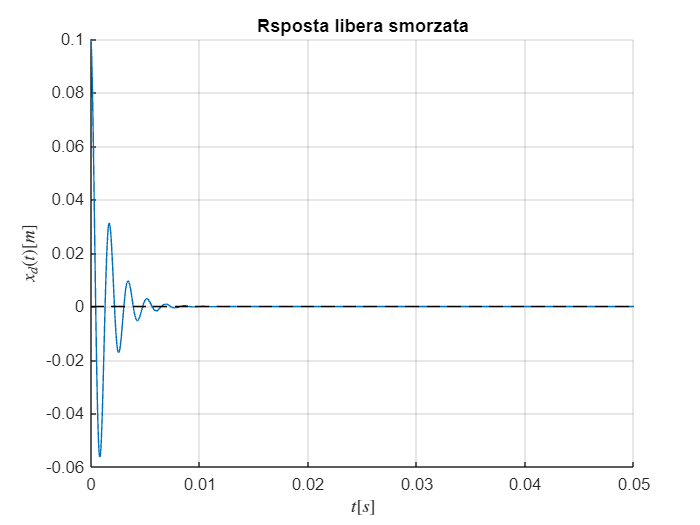

h=r/(2*hw*wn);
wd=wn*sqrt(1-h^2);
psid=atan(-v0/wd*x0);
Cd=x0/cos(psid);
xd = Cd*cos(wd*t+psid).*exp(-h*wn*t);

figure
hold on
plot(t,xd+x_eq)
plot([0 t(end)],[x_eq x_eq],'k--')
grid on
ylabel('${x}_{d}(t) [m]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')
title('Rsposta libera smorzata')

## STEP5.2 Risposta forzata

L'equazione di moto che descrive la risposta forzata del sistema è quella completa:


$$m\ddot{x} +r\dot{x} +\textrm{kx}=\textrm{ky}+r\dot{y}$$


La forzante ha la seguente forma:


$$\begin{array}{l}
y\left(t\right)=A\cdot \sin \left(\Omega t\right)=Ae^{i\left(\Omega t-\frac{\pi }{2}\right)} \\
\dot{y} \left(t\right)=i\Omega Ae^{i\left(\Omega t-\frac{\pi }{2}\right)} 
\end{array}$$


La risposta forzata, a regime, poichè la forzante è monoarmonica e il sistema è lineare, è una funzione armonica alla stessa frequenza della forzante con ampiezza e fase che dipendono dalle caratteristiche e dalle condizioni iniziali del sistema:


$$\begin{array}{l}
x\left(t\right)=X_0 e^{i\left(\Omega t-\frac{\pi }{2}\right)} \\
\dot{x} \left(t\right)=X_0 {i\Omega e}^{i\left(\Omega t-\frac{\pi }{2}\right)} \\
\ddot{x} \left(t\right)=-X_0 \Omega^2 e^{i\left(\Omega t-\frac{\pi }{2}\right)} 
\end{array}$$



$$\left(-m\Omega^2 +\textrm{ir}\Omega +k\right)X_0 e^{i\left(\Omega t-\frac{\pi }{2}\right)} =\left(k+\textrm{ir}\Omega \right)Ae^{i\left(\Omega t-\frac{\pi }{2}\right)} \;\Longrightarrow \frac{X_0 }{A}=\frac{k+\textrm{ir}\Omega }{k-m\Omega^2 +\textrm{ir}\Omega }=\frac{1+\textrm{i2ha}}{1-a^2 +\textrm{i2ha}}\longrightarrow \left\lbrace \begin{array}{ll}
\left|\frac{X_0 }{A}\right| & \\
\psi  & 
\end{array}\right.$$



$$x\left(t\right)=\left|X_0 \right|\cdot \sin \left(\Omega t+\psi \right)$$


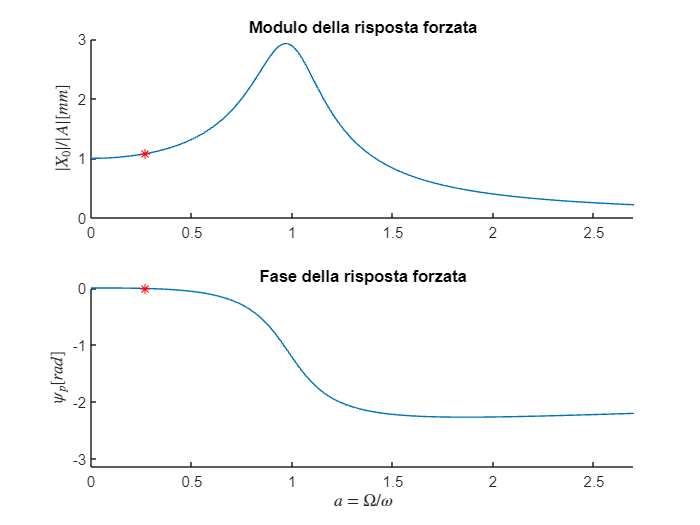

w=[0:0.01:10000];
a=w/wn;

H_vet=(1+1i*2*h*a)./(1-a.^2+1i*2*h*a); %N.B.: H è la funzione di trasferimento (x0/A)
H_vet_mod=abs(H_vet);
H_vet_fase=angle(H_vet);

aW=W/wn;
H=(1+1i*2*h*aW)/(1-aW^2+1i*2*h*aW);
H_mod=abs(H);
H_fase=angle(H);

figure
subplot(211)
hold on
plot(a,H_vet_mod)
plot(aW,H_mod,'r*')
ylabel('${|{X}_{0}}|/|{A}| [mm]$','Interpreter','latex')
title('Modulo della risposta forzata')
axis([0 2.7 0 3])
subplot(212)
hold on
plot(a,H_vet_fase)
plot(aW,H_fase,'r*')
ylabel('${\psi}_{p} [rad]$','Interpreter','latex')
xlabel('$a={\Omega}/{\omega}$','Interpreter','latex')
title('Fase della risposta forzata')
axis([0 2.7 -pi 0])

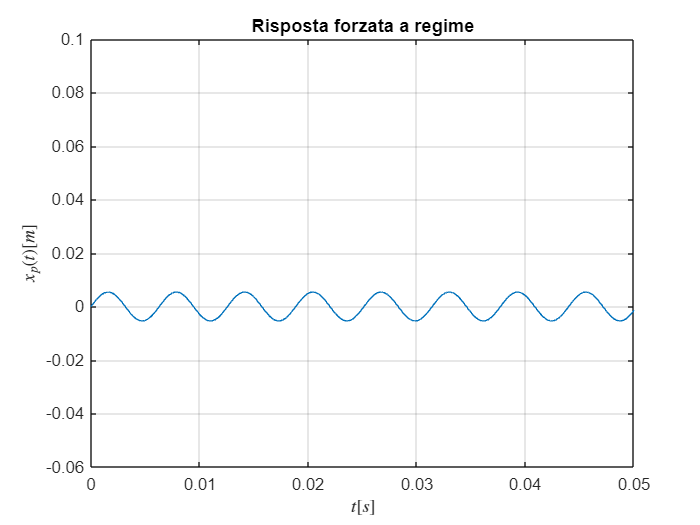

xp=H_mod*A*sin(W*t+H_fase);
figure
plot(t,xp)
axis([0 0.05 -0.06 0.1])
grid on
ylabel('${x}_{p}(t) [m]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')
title('Risposta forzata a regime')

La risposta completa del sistema si ottiene sommando la risposta libera smorzata e la risposta forzata:


$$x\left(t\right)=x_d \left(t\right)+x_p \left(t\right)=x_d \left(t\right)=e^{-\alpha t} C_d \cdot \cos \left(\omega_d t+\psi_d \right)+\left|X_0 \right|\cdot \sin \left(\Omega t+\psi \right)$$


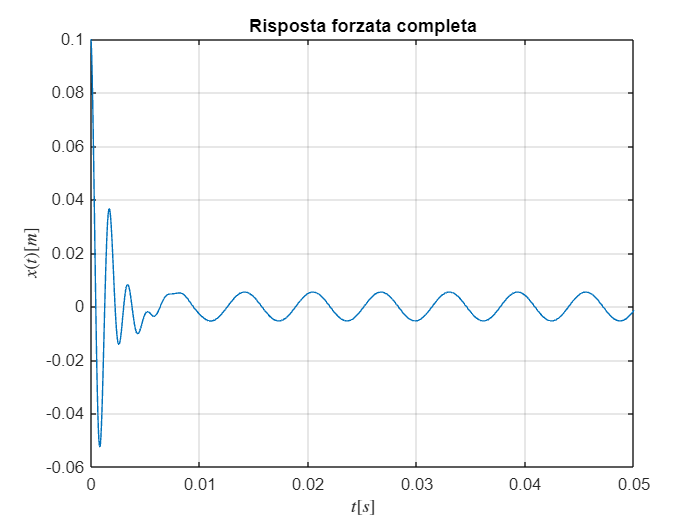

figure
plot(t,xp+xd+x_eq)
grid on
ylabel('$x(t) [m]$','Interpreter','latex')
xlabel('$t [s]$','Interpreter','latex')
title('Risposta forzata completa')

## STEP5.3 Scelta progettuale

La pulsazione di eccitazione $\Omega$ scelta risulta essere circa un quarto della pulsazione naturale $\omega_n$.

Dal grafico del modulo, si evince che il modulo per $\Omega =0$ è pari ad 1, mentre per $\Omega \longrightarrow \infty$ tende a 0. Si deduce che, per $\Omega =0$, lo spostamento relativo risulta essere nullo, mentre, per $\Omega \longrightarrow \infty$, la massa rimane pressochè ferma. Sulla base di queste considerazioni sarebbe opportuno eccitare il sistema con una pulsazione $\Omega$ vicina alla pulsazione naturale $\omega_n$.